clear
audio = "heyhey.wav";
[Y, fs] = audioread(audio{1});
plot(Y)

raw_audio = Y(:,:);
step = 24.271;


Ymax = max(Y)

Ymax = 0.8347

Ymin = min(Y)

Ymin = -0.8619

delta = .0695

delta = 0.0695

stepsize = (Ymax-Ymin) / step

stepsize = 0.0699

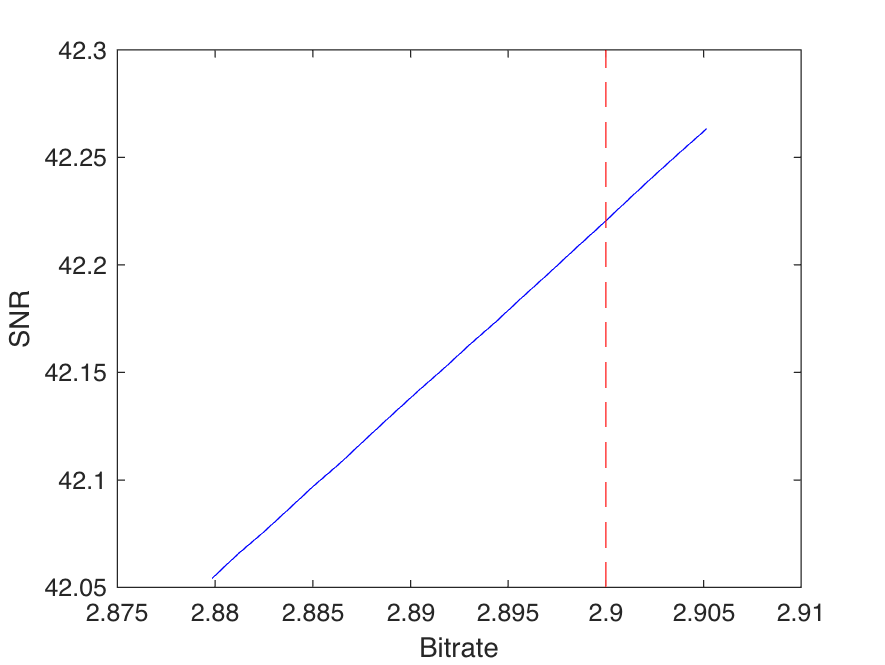

blocksize = 512;

raw_audio_blocks = reshape(raw_audio, blocksize,[] );

for k = 1:20

    delta = 0.069+k*10^-4;

    
    C = num2cell(raw_audio_blocks, 1); 
    columnSums = mdct(raw_audio, blocksize);
    y_transformed = dct(raw_audio);
    y_quantize = quantize(columnSums, delta);
    c = uniqueIndex(y_quantize);
    num = accumarray(c,1);
    p = num/sum(num);
    %plot(y_transformed);
    rate = huffman(p);
    H = entropyOfDistribution(p);
    yhat = imdct(y_quantize*delta);
    %plot(raw_audio);
    diff = raw_audio - (yhat);
    % Distorsion
    D = mean(mean(diff.^2));
    %SNR
    SNR = 10*log10(var(raw_audio)/D);
    %fprintf('Blocksize:\n %.0f',blocksize)
    %fprintf('Rate: %.4f dB',rate)
    %fprintf('Entropy: %.4f dB',H)
    %fprintf('SNR: %.2f dB',SNR)
    SNR_arr(k) = SNR;
    rate_arr(k) = rate;
end
hold on
xline(2.9, '--r')
plot(rate_arr, SNR_arr, 'b')
xlabel('Bitrate');
ylabel('SNR');
hold off

%columnSums = cellfun(@dct, C, 'UniformOutput',false);
%max(y_transformed)
%min(y_transformed)




%y_quantize = cellfun(@(row) quantize(row, delta), columnSums, 'UniformOutput',false);


%c = cellfun(@(row) uniqueIndex(row), y_quantize, 'UniformOutput',false);



%c = reshape(cell2mat(c), [], 1)
%[~,~,c] = unique(y_quantize)



% data rate



%I = y_quantize ; 
%y_quantize = zeros(1,8192000);
%y_quantize(1:1,1:6000000) = I;

% Inverse cosine transform
%yhat = cellfun(@(row) idct(row*delta), y_quantize,'UniformOutput',false);




%test = reshape(cell2mat(yhat),[],1);
%plot(test)


%yhat = idct(y_quantize*delta);
%diff = raw_audio_blocks - cell2mat(yhat);





%AAodd = Aodd.*1/sqrt(2) + Aeven.*1/sqrt(2);
%AAeven = Aeven.*1/sqrt(2) - Aodd.*1/sqrt(2) ;

%plot(Aodd,Aeven,'.')
%plot(AAodd, AAeven, '.')


%xhat = q(1:10000)*delta;



%l = huffman(xhat);

function out = quantize(x, delta)

out = round(x/delta);

end
function index = uniqueIndex(x)

[~,~,index] = unique(x);

end